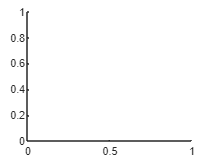

% Построение для отношений амплитуд с ЛДФ
clear all
hold off

fpass1=[0.6,1.6];
%fpass1 = 1.6
%fpass2 = [0.01,0.6];
%fpass = 2;
NAMES = ["2025-01-24";"2025-02-04";"2025-02-20";"2025-04-11";"2025-05-29"]; %"2025-01-24";"2025-02-04";;"2025-02-20"
for m = 1:length(NAMES)

NAME = convertStringsToChars(NAMES(m)); %Название папки с данными
load(strcat('OUT/',NAME,'/PARAM.mat'));
load(strcat('OUT/',NAME,'/DATA_LDF.mat'));
%Чтение файла расписания процедуры
TT = importtt(strcat('DATA/',NAME,'/TIMETABLE.xlsx'),NAME);
N = length(TT.DATE);
means_amp2 = zeros(N,1);
std_dev_amp2 = zeros(N,1);
means_ldf1 = zeros(N,1);
std_dev_ldf = zeros(N,1);
num_EC = 4;%номер этапа, где ИК и надо вырезать
for i = 1:N
    if i == N
        Data_amp2{i} = table2array(PARAM(find((PARAM.NAME > TT.DATE(i))),"dR2"));
        Data_amp1{i} = table2array(PARAM(find((PARAM.NAME > TT.DATE(i))),"BASE2"));
        %temp_ldf_pulse = bandpass(DATA_LDF.MC(find(DATA_LDF.DATE_LDF>TT.DATE(i)& (abs(DATA_LDF.MC) < 50))),fpass1,20);
        temp_ldf = bandpass(DATA_LDF.MC(find(DATA_LDF.DATE_LDF>TT.DATE(i)& (abs(DATA_LDF.MC) < 50))),fpass1,20);
        temp_ldf = movmax(temp_ldf(abs(temp_ldf)<10),20)-movmin(temp_ldf(abs(temp_ldf)<10),20)
        %temp_ldf = temp_ldf(abs(temp_ldf)<10);
        %means_ldf1(i) = mean(temp_ldf_pulse./temp_ldf);
        means_ldf1(i) = mean(temp_ldf);
        data2{(m-1)*N+i} = temp_ldf;
        data1{(m-1)*N+i} = Data_amp2{i}./Data_amp1{i};
        std_dev_ldf (i) = std(temp_ldf);
        %Data_test_date_1 = table2array(DATA(find(DATA.DATE < TT.DATE(2) & (DATA.DATE > TT.DATE(1))),"DATE"));
        means_amp2(i) = mean(Data_amp2{i}./Data_amp1{i});
        std_dev_amp2(i) = std(Data_amp2{i}./Data_amp1{i});
    elseif i ~= num_EC
        Data_amp2{i} = table2array(PARAM(find(PARAM.NAME < TT.DATE(i+1) & (PARAM.NAME > TT.DATE(i))),"dR2"));
        Data_amp1{i} = table2array(PARAM(find(PARAM.NAME < TT.DATE(i+1) & (PARAM.NAME > TT.DATE(i))),"BASE2"));
        %Data_test_date_1 = table2array(DATA(find(DATA.DATE < TT.DATE(2) & (DATA.DATE > TT.DATE(1))),"DATE"));
        %temp_ldf_pulse = bandpass(DATA_LDF.MC(find(DATA_LDF.DATE_LDF>TT.DATE(i)& DATA_LDF.DATE_LDF<TT.DATE(i+1)&(abs(DATA_LDF.MC) < 50))),fpass1,20);
        temp_ldf = bandpass(DATA_LDF.MC(find(DATA_LDF.DATE_LDF>TT.DATE(i)& DATA_LDF.DATE_LDF<TT.DATE(i+1)&(abs(DATA_LDF.MC) < 50))),fpass1,20);
        temp_ldf = movmax(temp_ldf(abs(temp_ldf)<10),20)-movmin(temp_ldf(abs(temp_ldf)<10),20)
        %temp_ldf = temp_ldf(abs(temp_ldf)<10);
        %means_ldf1(i) = mean(temp_ldf_pulse./temp_ldf);
        means_ldf1(i) = mean(temp_ldf);
        std_dev_ldf (i) = std(temp_ldf);
        data2{(m-1)*N+i} = temp_ldf;
        data1{(m-1)*N+i} = Data_amp2{i}./Data_amp1{i};
        means_amp2(i) = mean(Data_amp2{i}./Data_amp1{i});
        std_dev_amp2(i) = std(Data_amp2{i}./Data_amp1{i});
    else
        means_ldf1(i) = nan;
        std_dev_ldf(i) = nan;
        means_amp2(i) = nan;
        std_dev_amp2(i) = nan;
    end
end
x=1:length(TT.DATE)
data = [means_amp2];
DATA_Means{m} = means_amp2;
DATA_Q1{m} = quantile(means_amp2,0.25);
DATA_Q3{m} = quantile(means_amp2,0.75);
sum1(m) = means_amp2(1);
sum2(m) = means_amp2(2);
sum3(m) = means_amp2(3);
sum4(m) = means_amp2(4);
sum5(m) = means_amp2(5);
sum6(m) = means_amp2(6);
DATA_std{m} = std_dev_amp2;
DATA_Means_ldf{m} = means_ldf1;
DATA_Q1_ldf{m} = quantile(means_ldf1,0.25);
DATA_Q3_ldf{m} = quantile(means_ldf1,0.75);
sum1_ldf(m) = means_ldf1(1);
sum2_ldf(m) = means_ldf1(2);
sum3_ldf(m) = means_ldf1(3);
sum4_ldf(m) = means_ldf1(4);
sum5_ldf(m) = means_ldf1(5);
sum6_ldf(m) = means_ldf1(6);
DATA_std_ldf{m} = std_dev_ldf;
std_data = [std_dev_amp2,std_dev_ldf];
%fig = plot(x,data,x,means_ldf)
% tiledlayout(2,1)
% ax1 = nexttile;
% errorbar(x,means_amp2,std_dev_amp2,LineWidth = 3);
% grid on
% hold on
% ax2 = nexttile;
% errorbar(x,means_ldf1,std_dev_ldf,LineWidth = 3);
% linkaxes([ax1 ax2],'x')% ax3
% grid on
end

temp_ldf =     5.0874
    5.5455
    6.2821
    6.7177
    6.8964
    6.9067
    6.9067
    6.9067
    6.9277
    7.1429


temp_ldf =     3.8971
    4.3079
    5.0307
    5.5296
    5.8100
    5.9129
    5.9129
    5.9129
    5.9129
    5.9129


temp_ldf =     4.0174
    4.9968
    5.7560
    6.2554
    6.5039
    6.5483
    6.5483
    6.5483
    6.5483
    6.5483


temp_ldf =     3.6143
    4.0186
    4.5582
    4.9097
    5.1069
    5.2056
    5.2658
    5.3344
    5.4343
    5.5615


temp_ldf =     3.6873
    4.5444
    5.1792
    5.5609
    5.7076
    5.7076
    5.7076
    5.7076
    5.7076
    5.7076


x =      1     2     3     4     5     6


temp_ldf =     5.9307
    7.1070
    7.8946
    8.2770
    8.3179
    8.3179
    8.3179
    8.3179
    8.3179
    8.3179


temp_ldf =     5.3405
    5.8452
    5.8779
    5.8779
    5.8779
    5.8779
    5.8779
    5.8779
    5.8779
    5.8779


temp_ldf =     4.6281
    5.3128
    6.0274
    6.4334
    6.5632
    6.5632
    6.5632
    6.5632
    6.5632
    6.5632


temp_ldf =     6.1274
    6.1274
    6.1274
    6.1274
    6.1274
    6.1274
    6.1274
    6.1274
    6.1274
    6.1274


temp_ldf =     4.0427
    4.0427
    4.0427
    4.3125
    5.6573
    6.9129
    7.9521
    8.6640
    8.9694
    8.9694


x =      1     2     3     4     5     6


temp_ldf =     4.7302
    5.9508
    6.9271
    7.6043
    7.9848
    8.1160
    8.1160
    8.1160
    8.1160
    8.1160


temp_ldf =     7.0194
    7.0194
    7.0194
    7.4560
    8.0229
    8.3248
    8.4501
    8.5045
    8.5836
    8.7494


temp_ldf =     3.9038
    4.6110
    5.1586
    5.4409
    5.5010
    5.5010
    5.5010
    5.5010
    5.5010
    5.5010


temp_ldf =     6.2773
    6.6760
    7.8249
    8.6295
    9.0920
    9.2676
    9.2676
    9.2676
    9.2676
    9.2676


temp_ldf =     5.9447
    7.5341
    8.8109
    9.6858
   10.1427
   10.2285
   10.2285
   10.2285
   10.2285
   10.2285


x =      1     2     3     4     5     6


temp_ldf =     6.8337
    8.2223
    9.1720
    9.6563
    9.7387
    9.7387
    9.7387
    9.7387
    9.7387
    9.7387


temp_ldf =     4.1399
    4.7695
    5.3944
    5.7712
    5.9359
    5.9581
    5.9581
    5.9581
    5.9581
    6.0354


temp_ldf =     4.8138
    5.8021
    6.4700
    6.7893
    6.7978
    6.7978
    6.7978
    6.7978
    6.7978
    6.7978


temp_ldf =     5.0470
    6.1491
    6.9206
    7.3261
    7.4031
    7.4031
    7.4031
    7.4031
    7.4031
    7.4031


temp_ldf =     5.6202
    6.4180
    7.4618
    8.1461
    8.4731
    8.5024
    8.5024
    8.5024
    8.5024
    8.5024


x =      1     2     3     4     5     6


temp_ldf =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


temp_ldf =     7.2027
    8.9291
   10.2134
   10.9774
   11.2426
   11.2426
   11.2426
   11.2426
   11.2426
   11.2426


temp_ldf =     5.8839
    7.1423
    8.0270
    8.4982
    8.5941
    8.5941
    8.5941
    8.5941
    8.5941
    8.5941


temp_ldf =     7.6895
    9.2463
   10.3173
   10.8549
   10.9072
   10.9072
   10.9072
   10.9072
   10.9072
   10.9072


temp_ldf =     5.8410
    7.0234
    7.8233
    8.2214
    8.2774
    8.2774
    8.2774
    8.2774
    8.2774
    8.2774


x =      1     2     3     4     5     6


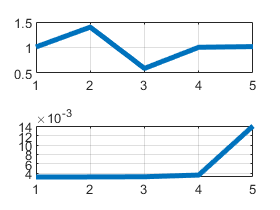

clear means_dr_r means_ldff
means_dr_r(1) = mean(sum1);
means_dr_r(2) = mean(sum2);
means_dr_r(3) = mean(sum3);

means_dr_r(4) = mean(sum5);
means_dr_r(5) = mean(sum6);

means_ldff(1) = mean(sum1_ldf);
means_ldff(2) = mean(sum2_ldf);
means_ldff(3) = mean(sum3_ldf);
means_ldff(4) = mean(sum5_ldf);
means_ldff(5) = mean(sum6_ldf);

tiledlayout(2,1)
ax1 = nexttile;
plot(means_dr_r,LineWidth = 3);
grid on
hold on
ax2 = nexttile;
plot(means_ldff,LineWidth = 3);
linkaxes([ax1 ax2],'x')% ax3
grid on

Q1_imp = quantile(sum6,0.25);
Q3_imp = quantile(sum6,0.75);

Q1_ldf = quantile(sum6_ldf,0.25);
Q3_ldf = quantile(sum6_ldf,0.75);

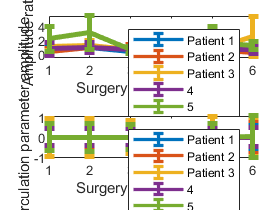

fig = figure();
set(gca,'fontsize',20)
tiledlayout(2,1)
ax1 = nexttile;
for i = 1:length(NAMES)
    errorbar(x,DATA_Means{i},DATA_std{i},LineWidth = 3)
    hold on

end
hold off
xlabel("Surgery phase number")
ylabel("Amplitude ratio")
legend(["Patient 1", "Patient 2", "Patient 3","4","5"])
ax2 = nexttile;
for i = 1:length(NAMES)
    errorbar(x,DATA_Means_ldf{i},DATA_std_ldf{i},LineWidth = 3)
    hold on

end
hold off
xlabel("Surgery phase number")
ylabel("Microcirculation parameter amplitude") 
legend(["Patient 1", "Patient 2", "Patient 3","4","5"])
linkaxes([ax1 ax2],'x')% ax3

% Играемся со статистической значимостью

data_all{1} = [data1{1};data1{7};data1{13};data1{19};data1{25}];
data_all{2} = [data1{2};data1{8};data1{14};data1{20};data1{26}];
data_all{3} = [data1{3};data1{9};data1{15};data1{21};data1{27}];
data_all{4} = [data1{5};data1{11};data1{17};data1{23};data1{29}];
data_all{5} = [data1{6};data1{12};data1{18};data1{24};data1{30}];

data_all_ldf{1} = [data2{1};data2{7};data2{13};data2{19};data2{25}];
data_all_ldf{2} = [data2{2};data2{8};data2{14};data2{20};data2{26}];
data_all_ldf{3} = [data2{3};data2{9};data2{15};data2{21};data2{27}];
data_all_ldf{4} = [data2{5};data2{11};data2{17};data2{23};data2{29}];
data_all_ldf{5} = [data2{6};data2{12};data2{18};data2{24};data2{30}];
%[h, p, ci, stats] = ttest2(sum3_ldf, sum2_ldf, 'Vartype', 'unequal')


% Статистика для импеданса
means1= zeros(1,5);
Q1s= zeros(1,5);
Q3s= zeros(1,5);
ps = zeros(1,4);
hs = zeros(1,4);

for i=1:5
    means1(i) = median(data_all{i});
    Q1s(i) = quantile(data_all{i},0.25);
    Q3s(i) = quantile(data_all{i},0.75);
    if i<5
    [ps(i), hs(i), stats] = ranksum(data_all{i}, data_all{i+1});
    end
end

% Статистика для ЛДФ
means1_ldf= zeros(1,5);
Q1s_ldf= zeros(1,5);
Q3s_ldf= zeros(1,5);
ps_ldf = zeros(1,4);
hs_ldf = zeros(1,4);

for i=1:5
    means1_ldf(i) = median(data_all_ldf{i});
    Q1s_ldf(i) = quantile(data_all_ldf{i},0.25);
    Q3s_ldf(i) = quantile(data_all_ldf{i},0.75);
    if i<5
    [ps_ldf(i), hs_ldf(i), stats] = ranksum(data_all_ldf{i}, data_all_ldf{i+1});
    end
end

corrcoef(means1_ldf(1:5),means1(1:5))

ans =     1.0000    0.5768
    0.5768    1.0000


ldf = temp_ldf

ldf =     4.3797
   -6.5085
  -16.7840
  -26.3229
  -35.0000
  -42.6963
  -49.3048
  -54.7369
  -58.9266
  -61.8354


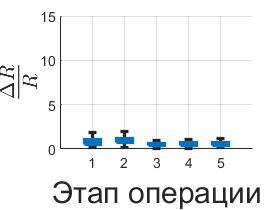

data = data_all;
data_no_outliers = cell(size(data));

for i = 1:length(data)
    currentData = data{i};
    
    % Calculate IQR bounds
    Q1 = quantile(currentData, 0.25);
    Q3 = quantile(currentData, 0.75);
    IQR = Q3 - Q1;
    lowerBound = Q1 - 1.5 * IQR;
    upperBound = Q3 + 1.5 * IQR;
    
    % Remove outliers
    data_no_outliers{i} = currentData(currentData >= lowerBound & currentData <= upperBound);
end

% Create boxchart without outliers
values = [];
groups = [];

for i = 1:length(data)
    currentData = data{i};
    values = [values; currentData(:)];
    groups = [groups; repmat(i, numel(currentData), 1)];
end

fig = figure();
set(gca,'fontsize',20)
boxchart(groups, values,'MarkerStyle','none','LineWidth',2); % Hide any remaining outliers
xlabel('Этап операции','FontSize', 18);
ylabel('$\frac{\Delta R}{R}$', 'Interpreter', 'latex','FontSize', 18)
grid on
xticks(1:5);

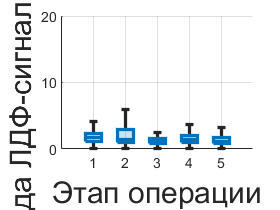

data = data_all_ldf;
data_no_outliers = cell(size(data));

for i = 1:length(data)
    currentData = data{i};
    
    % Calculate IQR bounds
    Q1 = quantile(currentData, 0.25);
    Q3 = quantile(currentData, 0.75);
    IQR = Q3 - Q1;
    lowerBound = Q1 - 1.5 * IQR;
    upperBound = Q3 + 1.5 * IQR;
    
    % Remove outliers
    data_no_outliers{i} = currentData(currentData >= lowerBound & currentData <= upperBound);
end

% Create boxchart without outliers
values = [];
groups = [];

for i = 1:length(data)
    currentData = data{i};
    values = [values; currentData(:)];
    groups = [groups; repmat(i, numel(currentData), 1)];
end

fig = figure();
set(gca,'fontsize',20)
boxchart(groups, values,'MarkerStyle','none','LineWidth',2); % Hide any remaining outliers
xlabel('Этап операции','FontSize', 18);
ylabel('Амплитуда ЛДФ-сигнала, перф. ед.','FontSize', 18)
grid on
xticks(1:5);

% Построение типовых форм для статьи
clear all
NAME = '2025-02-20';
TT = importtt(strcat('DATA/',NAME,'/TIMETABLE.xlsx'),NAME);
load(strcat('OUT/',NAME,'/CYCLE_DATA.mat'));
load(strcat('OUT/',NAME,'/DATA_LDF.mat'));

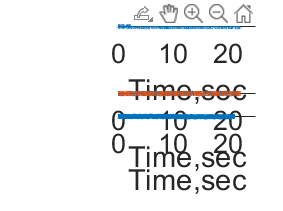

% Построение нескольких циклов вместе
fig = figure();
nstart = 4280;
nend = 4300;
last_time = 0;
last_time_ldf = 0;
data_time = [];
data_ecg = [];
data_rheo1 = [];
data_rheo2= [];


val = DATA_LDF.MC((DATA_LDF.DATE_LDF >= CYCLE_DATA{nstart}.NAME ) & (DATA_LDF.DATE_LDF <= (CYCLE_DATA{nstart}.NAME+seconds(max(CYCLE_DATA{nstart}.TIME)))));
time =  DATA_LDF.TIME_LDF((DATA_LDF.DATE_LDF >= CYCLE_DATA{nstart}.NAME ) & (DATA_LDF.DATE_LDF <= (CYCLE_DATA{nstart}.NAME+seconds(max(CYCLE_DATA{nstart}.TIME)))));

data_ldf = [];
time_ldf = [];
for i=(nstart):nend
    
    data_time = [data_time;(CYCLE_DATA{i}.TIME+last_time)];
    last_time = max(data_time);
    data_ecg = [data_ecg;CYCLE_DATA{i}.ECG];
    time1 = [CYCLE_DATA{i}.TIME(1);CYCLE_DATA{i}.TIME(end)];
    value1 = [CYCLE_DATA{i}.RHEO2(1);CYCLE_DATA{i}.RHEO2(end)];
    coefs1 = coeffvalues(fit(time1,value1,'poly1'));
    DATA_TEMP2 = CYCLE_DATA{i}.RHEO2;
    CYCLE_DATA{i}.RHEO2 = DATA_TEMP2 - coefs1(1)*CYCLE_DATA{i}.TIME;
    data_rheo1 = [data_rheo1;-CYCLE_DATA{i}.RHEO1];
    data_rheo2 = [data_rheo2;-CYCLE_DATA{i}.RHEO2];
    
    val = DATA_LDF.MC((DATA_LDF.DATE_LDF >= CYCLE_DATA{i}.NAME ) & (DATA_LDF.DATE_LDF <= (CYCLE_DATA{i}.NAME+seconds(max(CYCLE_DATA{i}.TIME)))));
    time =  DATA_LDF.TIME_LDF((DATA_LDF.DATE_LDF >= CYCLE_DATA{i}.NAME ) & (DATA_LDF.DATE_LDF <= (CYCLE_DATA{i}.NAME+seconds(max(CYCLE_DATA{i}.TIME)))));

    data_ldf = [data_ldf;val];
    time_ldf = [time_ldf;time-time(1)+last_time_ldf];
    last_time_ldf = max(time_ldf);

end
fontsize(fig, 28, "points");

tiledlayout(3,1);

ax1 = nexttile;
plot(data_time,-data_ecg+0.15,LineWidth = 3);
xlabel("Time,sec");
ylabel("ECG,V");
grid on
set(gca,'fontsize',16)
ax2 = nexttile;


plot(data_time,data_rheo1, data_time,data_rheo2,LineWidth = 3);
xlabel("Time,sec");
ylabel("-Rheo, mOhm");
grid on
set(gca,'fontsize',16)
ax3 = nexttile;


%plot(time_ldf,bandpass(data_ldf,[0.6,1.6],20),LineWidth = 3);
plot(time_ldf,data_ldf,LineWidth = 3);
xlabel("Time,sec"); 
ylabel("MC parameter,units");
grid on
set(gca,'fontsize',16)
linkaxes([ax1 ax2,ax3],'x')% ax3

CYCLE_DATA{nstart}.NAME

ans = datetime
   20-Feb-2025 13:23:41
